# EV Charging Infrastructure Research

K. Thach

Let's look at some basic datasets first. The CSV output from the AFD EV-Pro lite tool. Data is in 15 min intervals.

%How many charging stations are available in Charlotte,NC?
clt = readtable('datasets/Electrical_Charging_Stations_CLT.csv');


figure
geoscatter(clt.Latitude,clt.Longitude,'filled')
geobasemap streets

% Create 15 min. columns
Timestamp = (datetime('2020-06-30 00:00:00') : minutes(15) : datetime('2020-06-30 23:45:00')).';
Timestamp.Format = 'yyyy-MM-dd HH:mm:ss';
Timevec = datetime(Timestamp,"Format",'HH:mm');

figure 
area(Timevec,EV_CLT_WeekDay.publicl2*.001)
hold on;
area(Timevec,EV_CLT_WeekDay.publicl3*.001)
area(Timevec,EV_CLT_WeekDay.homel1*.001)
area(Timevec,EV_CLT_WeekDay.homel2*.001)
area(Timevec,EV_CLT_WeekDay.workl1*.001)
area(Timevec,EV_CLT_WeekDay.workl2*.001)
datetick('x','HH:MM')
xlabel('Hour of Day')
ylabel('Grid Load (MW)')
legend('Public L2','Public L3','Home L1','Home L2','Work L1','Work L2')
title('Weekday')

figure 
area(Timevec,EV_CLT_Weekend.publicl2*.001)
hold on;
area(Timevec,EV_CLT_Weekend.publicl3*.001)
area(Timevec,EV_CLT_Weekend.homel1*.001)
area(Timevec,EV_CLT_Weekend.homel2*.001)
area(Timevec,EV_CLT_Weekend.workl1*.001)
area(Timevec,EV_CLT_Weekend.workl2*.001)
datetick('x','HH:MM')
xlabel('Hour of Day')
ylabel('Grid Load (MW)')
legend('Public L2','Public L3','Home L1','Home L2','Work L1','Work L2')
title('Weekend')

% Hot Day - Worst Case Scenario

figure 
plot(Timevec,EV_CLT_WDH.homel1*.001,'LineWidth',3)
hold on;
plot(Timevec,EV_CLT_WDH.homel2*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WDH.publicl2*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WDH.publicl3*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WDH.workl1*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WDH.workl2*.001,'LineWidth',3)
datetick('x','HH:MM')
xlabel('Hour of Day')
ylabel('Grid Load (MW)')
legend('Public L3','Public L2','Home L1','Home L2','Work L1','Work L2')
title('Weekday')

figure 
plot(Timevec,EV_CLT_WEH.homel1*.001,'LineWidth',3)
hold on;
plot(Timevec,EV_CLT_WEH.homel2*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WEH.publicl2*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WEH.publicl3*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WEH.workl1*.001,'LineWidth',3)
plot(Timevec,EV_CLT_WEH.workl2*.001,'LineWidth',3)
datetick('x','HH:MM')
xlabel('Hour of Day')
ylabel('Grid Load (MW)')
legend('Public L3','Public L2','Home L1','Home L2','Work L1','Work L2')
title('Weekend')


%Check out Big Box electric profiles

ev2bb = readtable('datasets\big_box_electric_profiles\ev_station_2port_50kW_2event.csv');

groceryprofile = readtable('datasets\big_box_grocery_profiles\bldg_big_box_grocery_phoenix.csv');

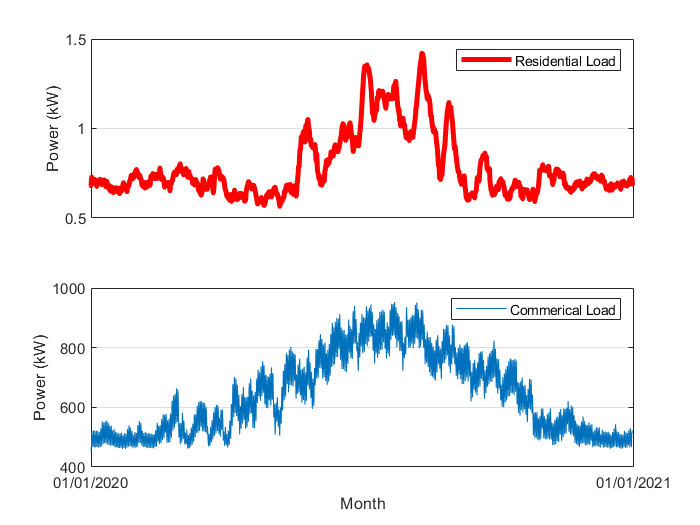

figure 
subplot(2,1,1)
plot(xt.Time(145:52560), movmean(xt.Household1(145:52560),1000)/1000,'red','LineWidth',3)
% datetick('x','mmm')
% xlabel('Month')
ylabel('Power (kW)')
set(gca,'XTick',[])
grid on;
legend('Residential Load')
hold on;
subplot(2,1,2)
plot(groceryprofile.Timestamp,movmean(groceryprofile.Power_kW_,1000))
xlabel('Month')
ylabel('Power (kW)')
datetick('x','mm/dd/yyyy')
legend('Commerical Load')
grid on;

js = datevec(groceryprofile.Timestamp);


%April 25;

figure 
plot(groceryprofile.Timestamp(165661:165661+1439,:),groceryprofile.Power_kW_(165661:165661+1439,:))

xt = readtable('R1.xlsx');
